# Proportional compensator design with Bode diagrams

This live script needs the control toolbox. Once profficient, students will probably find that the methods used in this script are mostly performed using sisotool.

A logical next file is ***lag_design_with_bode.mlx*** which looks at how to design a lag compensator beginning from a proportional compensator.

Users might also like to see  the app: ***proportional_design_phase_margin***.***mlapp*** which is part of the toolbox and automates much of the illustrations shown in the code below so users can focus on steps and concepts rather than coding.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Simple gain design using phase margin criteria

- Identifying the  gain from offset criteria for constant targets

- Identifying the gain from bandwidth/cross-over frequency criteria

- The app environment for doing proportional design: ***proportional_design_phase_margin***.***mlapp***

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

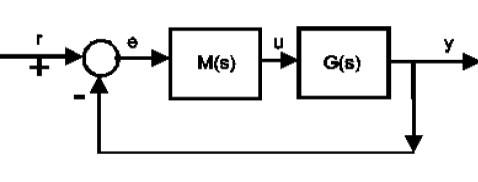

The closed-loop transfer function from target to output is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$

Frequency response design of M(s) focuses on the gain and phase margins as core indicators of likely closed-loop behaviour and indeed, although in practice, it is only the phase margin that is used actively for proportional design.  In the following we set out 3 typical design criteria which can be used to underpin systematic design.

- phase margin

- offset

- bandwidth/cross-over frequency

**NOTE**:  This livescript assumes that:  $M\left(s\right)=K$

### a) Phase margin and damping ratio as core design parameters

Typical statements are that the expected damping ratio of the closed-loop is linked, approximately, to the phase margin as given by the formulae here.

disp('Links between PM, damping ratio and expected overshoot')
damping_ratio = 0.4:.05:.9
overshoot = exp(-damping_ratio*pi./sqrt(1-damping_ratio.^2))
PM =atan(2*damping_ratio./sqrt(-2*damping_ratio.^2+sqrt(1+4*damping_ratio.^4)))*180/pi

One can determine the expected PM from desired overshoot or damping. So, given a desired overshoot of no more than 5-10% is common and thus a damping ratio of around 0.6, it is common to expect a PM of about 60 degrees to be  reasonable. More importantly, one expects that as the PM increases, damping increases and overshoot reduces so PM can also be used in a relative or incremental sense.

The gain margin should not be too small, but it would be unusual to have a good PM and poor GM and thus is not something to worry about too much about in an introductory level course.

### b) Offset as a core design criteria

Offset in the closed-loop is an obvious indicator of performance. Commonly one will want an offset of zero which necessitates the compensator to include an integrator, although in some cases non-zero offset may be acceptable where this relaxation allows better performance elsewhere.

For a simple feedback loop with system G(s) and compensator*** M(s)=K*** and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}=\frac{1}{1+G\left(0\right)K}$

disp('Illustration of typical offset to step computations with M=1')

Links between PM, damping ratio and expected overshoot


G=tf(1,[1 5 6]);

damping_ratio =     0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000


Gce = feedback(1,G);

overshoot =     0.2538    0.2053    0.1630    0.1263    0.0948    0.0681    0.0460    0.0284    0.0152    0.0063    0.0015


offset_percent = dcgain(Gce)*100

PM =    43.1176   47.6312   51.8273   55.6830   59.1873   62.3410   65.1564   67.6540   69.8600   71.8034   73.5137


**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)}=\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)K}$

This is more difficult to automate as we need to be sure the integrator is in place and remove the implied cancellation.

disp('Illustration of typical offset to ramp computations where integrator included and M=1')

Illustration of typical offset to step computations with M=1


G=tf(1,[1 5 6 0]);
K=1;
s = tf('s');

offset_percent = 85.7143

e_ramps = minreal(1/(s*G));
e_ramp = dcgain(e_ramps)


Illustration of typical offset to ramp computations where integrator included and M=1


disp('  ');
disp('END OF SECTION 1')

### c) Bandwidth as a design criteria

One measure of performance is settling time or equivalently speed of response. This is governed by the dominant poles of the closed-loop. However, pole position is a time domain property and thus, if working in the frequency domain, we want an equivalent property.  One such property is bandwidth.

Bandwidth is the range of frequencies for which gain is significant. For a closed-loop system where the target gain is unity, significant could be interpreted as something like:  $\textrm{Gain}\ge \sqrt{\frac{1}{2}}$$\;\;\;\;\;\;\;\;\;\;\;\;\;\left(\equiv -3\textrm{dB}\right)$ 

It so happens that we normally plot the Bode diagrams of the open-loop (i.e. loop transfer function) so we cannot infer the closed-loop gain explicitly. However, to a reasonable level of approximation:


$$\left|G\left(jw_c \right)M\right|=1\;\;\Rightarrow \;\left|G_c \left(jw_c \right)M\left(jw_c \right)\right|\approx$$

$$\sqrt{\frac{1}{2}}$$


In other words, with ***M(s)=K, *** the gain cross-over frequency $w_c$ which is where $\left|G\left(jw_c \right)K\right|=1,$ can be taken, approximately, to be the closed-loop bandwidth. This observation is useful because the gain cross-over frequency is an easier quantity to work with in design.

**Remark**: There exist approximating relationships between the settling time and the cut-off frequency, for example:


$$\frac{3}{w_c }<t_{\textrm{settle}} <\frac{10}{w_c }$$


as the closed loop can be approximated by a first order lag, if $w_c$ is on a -20dB/decade slope of the open loop Bode diagram and the next breaking point is far enough from $w_c$.Consequently, one could translate a desired settling time criteria into a target cross-over frequency criteria.

## 2. Simple gain design using phase margin criteria

For this section, assume the system includes an integrator so that the offset is zero. We want to design the gain of the compensator *M(s)* so that we have a desirable phase margin. This gives no control of the offset which may, as a consequence, be poor. 

The process can be systemised as follows.

- Decide desired PM and call this $\phi \ldotp$

- The PM is computed at the gain cross over frequency, so we can easily determine the frequency $w_c$ such that: $\arg \left(\textrm{GM}\right)=-180+\phi$. ***MANUAL ENTRY of ***$w_c$*** REQUIRED (so some approximation inevitable)!***

- Then chose the proportional K so that: $\left|\textrm{KG}\left(jw_c \right)\right|=1$

This will be clear following some illustration here. 

STEP 1: Data entry of *G(s)* and definition of target PM and production of base line bode diagram. For plotting purposes, the code below fixes  the frequency range so appropriate to the given *G(s)*. Change these values if required.

G=tf([1 1],[1 5 8 0]);
desiredPM = 50;
wmin=0.01;

e_ramp = 6

wmax=100;


figure; clf

END OF SECTION 1


bode(G,{wmin,wmax});grid;hold on
plot([wmin,wmax],[-180+desiredPM]*[1 1],'r')
text(wmin*10,-180+desiredPM+10,'-180+\phi')


STEP 2: Enter the desired cross over frequency $w_c$ on line below. **Make sure the green line crosses the intersect between the blue and red lines  on the open-loop bode plot.** Re-run section to update the plot.

wc=4.5; %% Edit the wc value here

plot([wc,wc],[-180,-90],'g','linewidth',3)
text(wc*1.1,-180+desiredPM+15,'wc')
title(['Bode diagram of G(s) and selection by eye of desired wc'])
disp('*****************************************')
disp(['Identified a suitable wc as ',num2str(wc),'rad/s'])

STEP 3: Determine the required gain *K* here automatically. If $w_c$ is computed correctly above, then the red compensated line will have $w_c$ as its gain cross over frequency, that is the intersect of the red and green line will be at 0dB. **Reminder that the phase diagram above is unchanged when we simply scale with a gain K.**

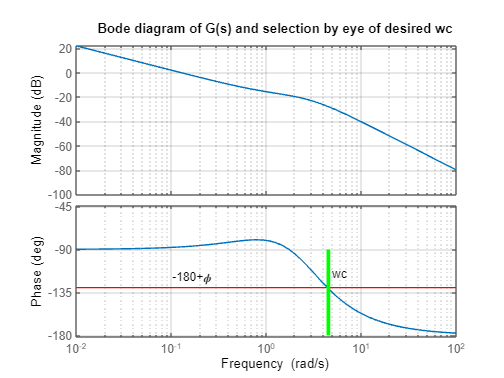

disp('*****************************************')
disp('Proportional design values')
K=1/bode(G,wc)
K_in_DB = 20*log10(K)

figure; clf
bodemag(G,G*K,{wmin,wmax});grid;hold on
plot([wc,wc],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)

title(['Bode diagram of G(s) and G(s)K'])

*****************************************


legend('G','GK','wc','0dB')

Identified a suitable wc as 4.5rad/s


disp('Margins with K chosen to meet PM criteria (approximately)')
disp(['Note how PM should closely match the target of ',num2str(desiredPM)])

*****************************************


figure;clf

Proportional design values


margin(G*K)

K = 25.0085

disp('BELOW is SECTION 2')

K_in_DB = 27.9618

disp(' ');

For completeness one could view the time domain closed-loop responses to see how behaviour differs before and after the proposed compensation. In this case, unsurprisingly, the compensated behaviour is much faster due to the original PM (for this example) being very large.

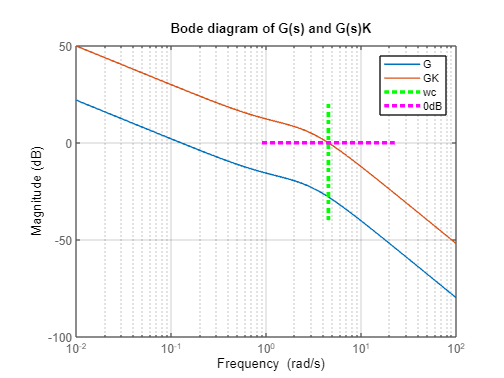

step(feedback(G,1),feedback(G*K,1),20);
title('Closed-loop output responses')
legend('K=1',['K = ',num2str(K)])
step(feedback(1,G),feedback(K,G),20);
title('Closed-loop input responses')
legend('K=1',['K = ',num2str(K)])

## 3. Identifying the  gain from offset criteria for constant targets

This file will not look at this design approach as it is not really a frequency response method and in general, offset would not be used in isolation from other criteria.

disp('Empty for now')

Margins with K chosen to meet PM criteria (approximately)


disp('BELOW is SECTION 3')

Note how PM should closely match the target of 50


disp(' ');

## 4. Identifying the gain from bandwidth/cross-over frequency criteria

For this method, define the desired cross-over frequency and then find the gain modification required to achieve this. Users should note that this gives no control of the PM which may, as a consequence, be poor! 

We can illustrate this with Bode diagrams as in section 1 above, but the design itself is a simple piece of algebra, that is:

- For desired cross over frequency $w_c$, choose the proportional K so that: $\left|\textrm{KG}\left(jw_c \right)\right|=1$

Let the target cross-over frequency be $w_c$=**wd**. You can edit the values in lines below for different examples of your choice.

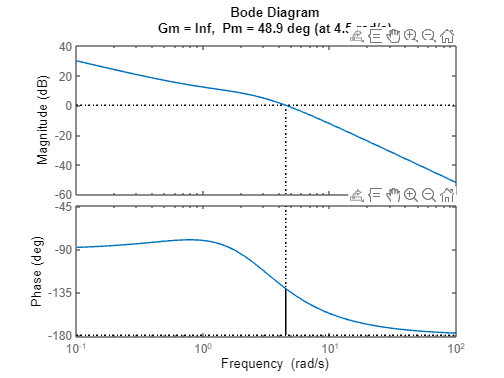

G=tf([1 1],[1 5 8 0]);

wd = 6;

BELOW is SECTION 2


disp('***************************************')

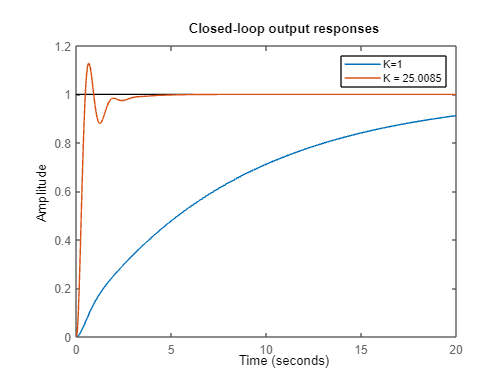

disp('Gain chosen to meet a bandwidth criteria only')
K=1/bode(G,wd)
K_in_DB = 20*log10(K)
figure; clf

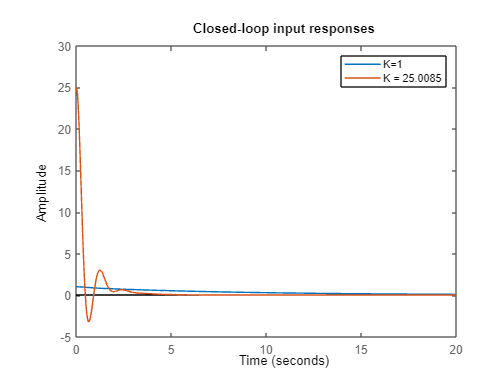

bodemag(G,G*K,{wmin,wmax});grid;hold on
plot([wd,wd],[-40,20],'g:','linewidth',3)
plot([wc/5,wc*5],[0,0],'m:','linewidth',3)

title(['Bode diagram of G(s) and G(s)K with wd = ',num2str(wd)])
legend('G','GK','wd','0dB')

disp('Margins with K chosen to meet bandwidth criteria')

Empty for now


disp('Note how PM may be poor')

BELOW is SECTION 3


figure;clf

margin(G*K)

For completeness one could view the time domain closed-loop responses to see how behaviour differs before and after the proposed compensation. In this case, unsurprisingly, the compensated behaviour is rather aggressive and unsatisfactory.

step(feedback(G,1),feedback(G*K,1),20);
title('Closed-loop output responses')
legend('K=1',['K = ',num2str(K)])

***************************************


step(feedback(1,G),feedback(K,G),20);

Gain chosen to meet a bandwidth criteria only


title('Closed-loop input responses')

K = 40.4782

legend('K=1',['K = ',num2str(K)])

K_in_DB = 32.1444

## 5. The app environment for doing proportional design: ***proportional_design_phase_margin***.***mlapp***

A screen dump of the app is given here. This file is part of the control101 toolbox so should appear under the apps tab once you have downloaded the toolbox.

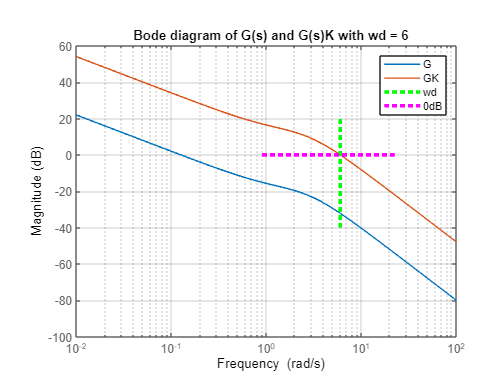

Margins with K chosen to meet bandwidth criteria


Note how PM may be poor


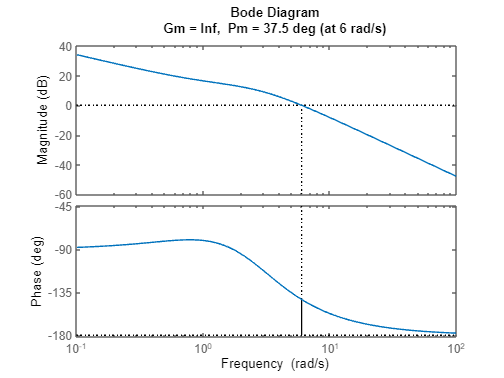

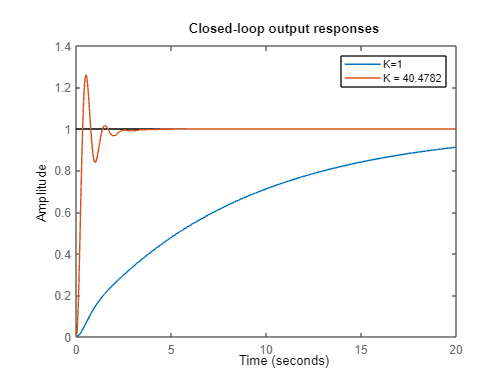

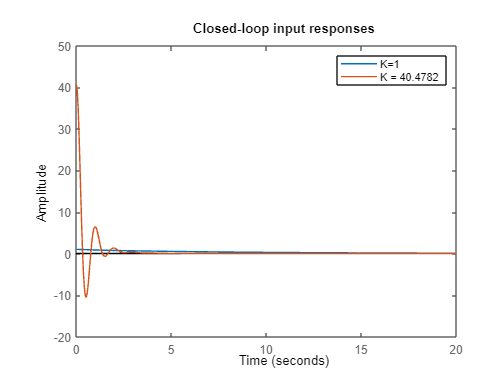

Opening existing copy - delete or rename this copy to access toolbox orginal


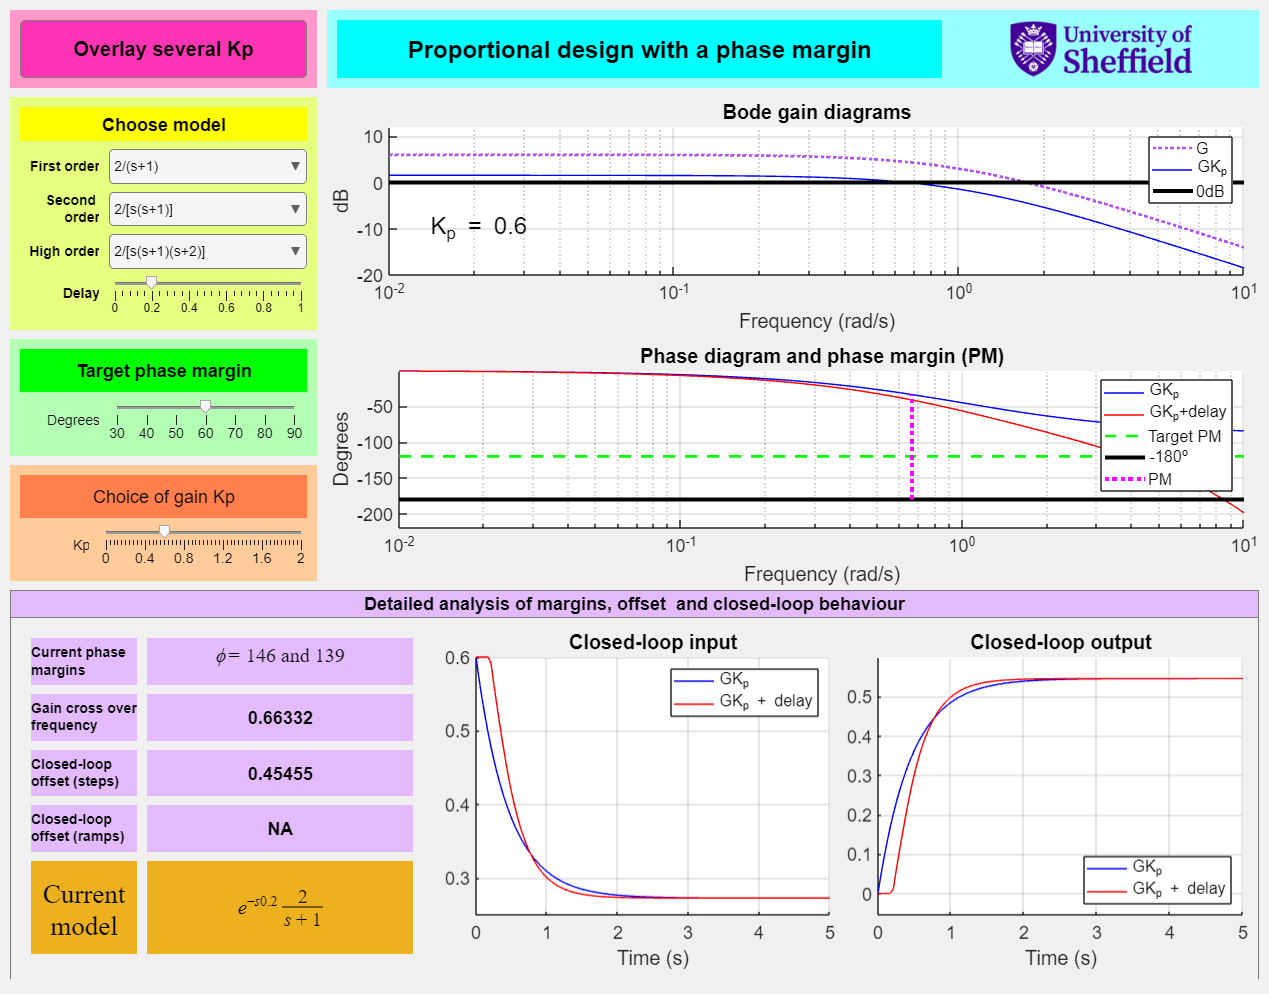

% proportional_design_phase_margin

The purpose of the app is to allow users to focus on concepts and learning rather than coding, whereas this livescript gives more focus on the mathematical and coding details. Hence the app allows users to carry out the design procedures above, but only on a predefined set of systems and to a relatively crude accuracy level.